# Projekt 3

#### **Przykład 1**

Histogram obrazu o niskim kontraście.

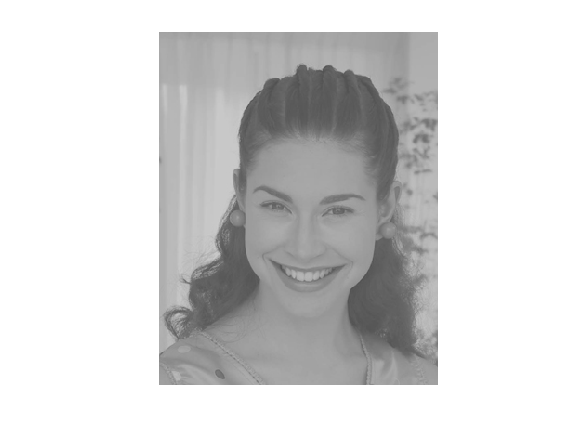

L1=imread('data/portret1.jpg');
figure;
imshow(L1);

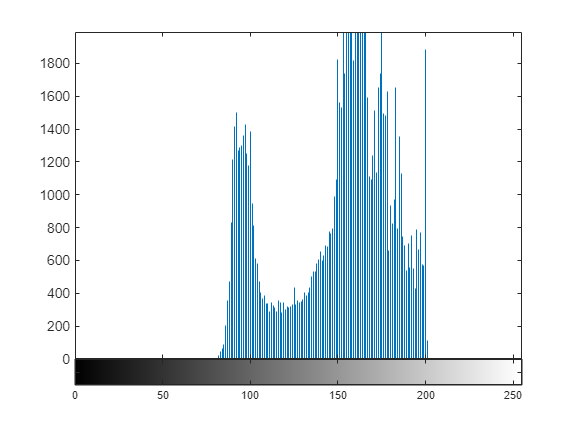

figure;
imhist(L1);

*L_out = imadjust(L_in, [LOW_IN; HIGH_IN], [LOW_OUT; HIGH_OUT],gamma) - mapuje wartości intensywności w obrazie L_in na nowe wartości w L_out w taki sposób, że wartości pomiędzy [LOW_IN; HIGH_IN] przetwarzane są na [LOW_OUT; HIGH_OUT] (rozciągnięcie histogramu)*

### Zadanie 1

Na podstawie analizy histogramów dokonaj korekcji obrazów *dziecko.jpg* oraz *widok.jpg*

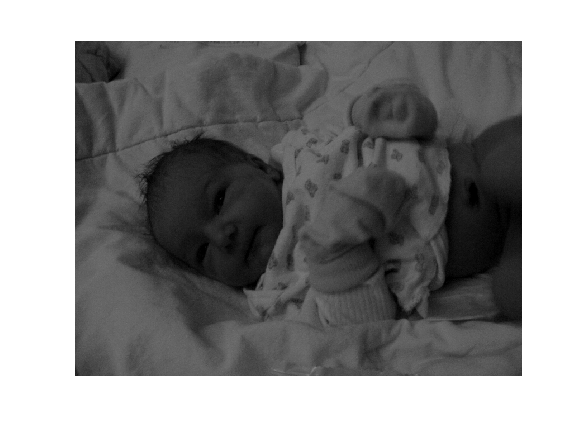

L1=imread('data/dziecko.jpg');
figure;
imshow(L1);

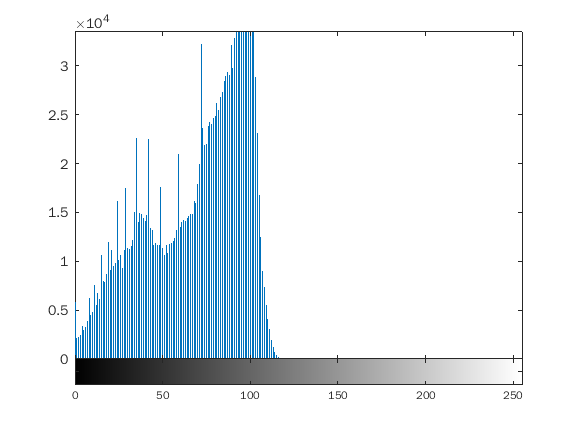

figure;
imhist(L1);

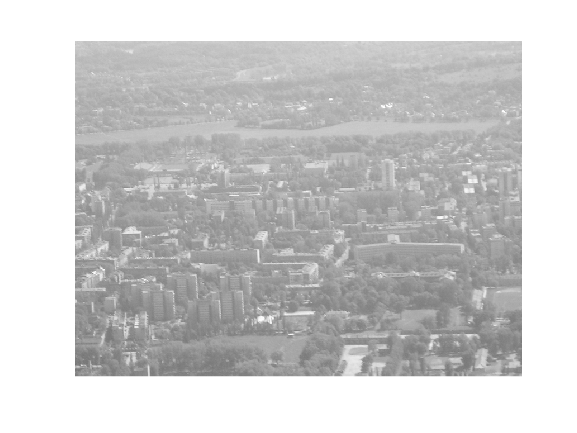


L2=imread('data/widok.jpg');
figure;
imshow(L2);

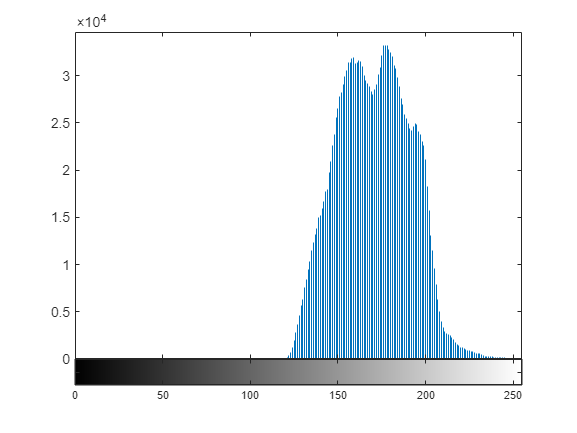

figure;
imhist(L2);


L3=imadjust(L1, [0/255, 125/255], [0,1], 1/2)

L3 = 1200×1600 uint8 matrix
   146   148   148   148   144   141   139   144   148   148   139   135   139   141   146   150   153   153   156   150   141   166   163   169   171   169   164   171   172   174   171   174   169   166   174   192   158   168   161   160   160   155   146   148   151   155   161   164   163   166
   151   148   144   156   151   141   135   146   155   142   133   142   146   141   144   156   155   153   156   153   148   164   160   163   166   169   160   169   172   172   171   171   168   163   144   151   161   160   160   158   156   153   135   144   148   153   160   161   168   172
   144   148   139   150   146   150   151   155   151   150   144   144   146   146   148   151   151   153   156   158   160   169   168   166   168   164   169   181   163   175   171   166   168   163   163   163   158   164   161   160   156   156   144   151   155   151   155   151   160   178
   150   153   139   144   139   141   144   144   148   146   150   

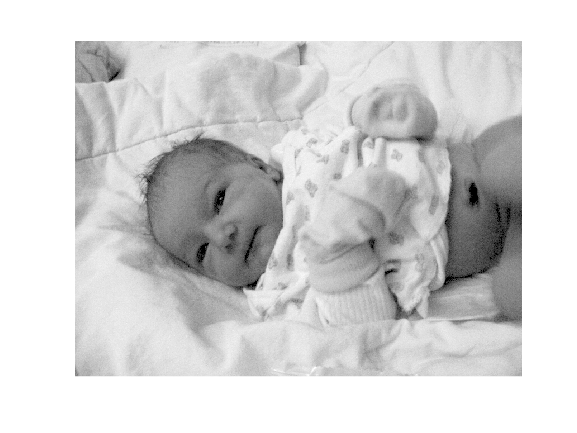

figure;
imshow(L3);

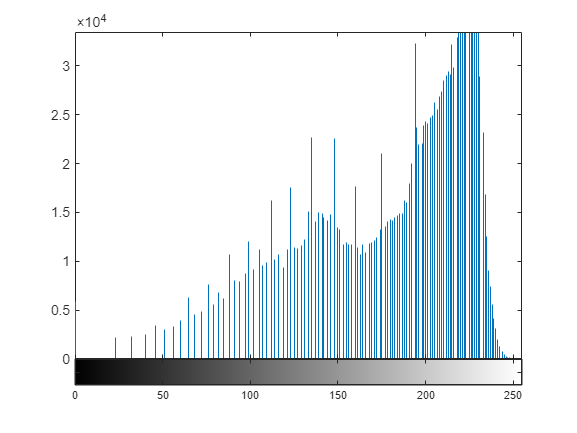

figure;
imhist(L3);



L4=imadjust(L2, [120/255, 240/255], [0,1])

L4 = 1200×1600 uint8 matrix
   183   185   187   189   185   183   181   181   185   185   185   187   187   181   168   164   164   166   170   174   174   172   174   176   170   168   166   168   168   168   166   159   166   164   166   168   166   166   168   168   168   168   168   168   168   170   172   174   174   174
   185   187   187   187   185   181   179   176   181   179   179   181   183   181   172   168   168   166   166   164   162   162   168   172   170   168   166   168   170   168   166   159   166   164   166   168   166   166   166   166   168   168   168   168   168   170   170   172   170   170
   183   183   185   185   183   181   179   176   170   170   172   174   176   179   176   176   172   170   170   168   166   166   170   172   172   170   168   170   172   170   168   164   162   162   162   164   164   162   162   164   166   166   166   166   166   168   170   170   166   166
   174   176   181   181   181   181   183   181   168   170   174   

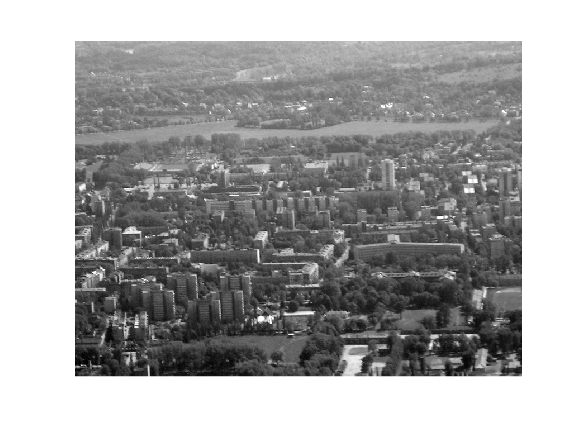

figure;
imshow(L4);

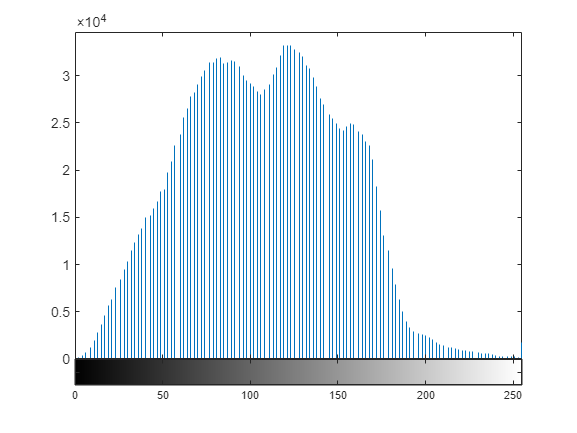

figure;
imhist(L4);

### Zadanie 2

Na obrazie *portret.jpg *wykonaj (po kolei) następujące kroki: 

- zmniejsz o 30 jasność wszystkich pikseli, których oryginalna jasność była mniejsza niż 80

- zwiększ o 30 jasność wszystkich pikseli, których oryginalna jasność była większa niż 180

- znajdź te piksele, które po przekształceniach osiągnęły skrajne wartości (0 oraz 255) i przedstaw je na szarym tle w nowym oknie obrazu

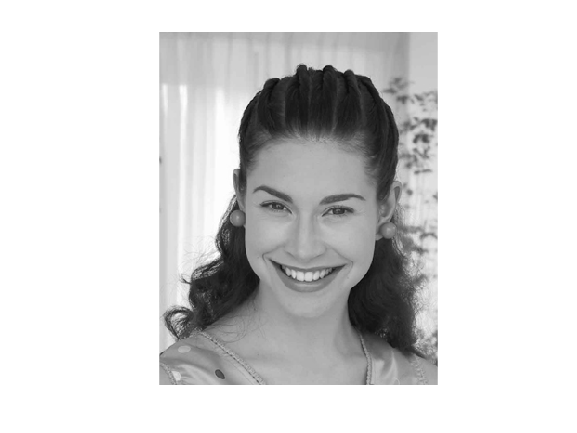

L5=imread('data/portret.jpg');
figure;
imshow(L5);

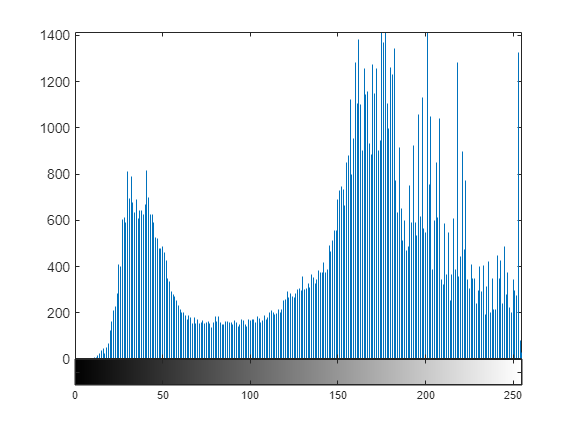


figure;
imhist(L5);

L5(find(L5<80)) = L5(find(L5<80))-30

L5 = 380×300 uint8 matrix
   171   174   175   175   175   175   175   177   179   177   175   174   176   174   172   169   168   168   169   173   176   178   178   178   175   175   176   176   176   175   172   170   164   161   165   168   171   173   173   171   168   171   171   171   171   171   172   173   173   173
   173   177   178   178   178   178   178   178   178   178   178   178   179   178   175   171   171   171   172   175   178   180   181   181   178   179   177   175   176   175   171   170   165   164   168   171   173   175   175   173   171   171   171   171   171   171   172   173   173   173
   177   180   181   181   181   180   180   179   178   178   180   181   181   180   178   175   173   174   174   177   181   182   183   183   180   181   179   176   176   175   172   170   167   168   171   173   175   178   178   175   173   172   171   171   171   171   172   173   173   173
   180   181   181   181   180   179   179   179   181   181   181   18

L5(find(L5>180)) = L5(find(L5>180))+30

L5 = 380×300 uint8 matrix
   171   174   175   175   175   175   175   177   179   177   175   174   176   174   172   169   168   168   169   173   176   178   178   178   175   175   176   176   176   175   172   170   164   161   165   168   171   173   173   171   168   171   171   171   171   171   172   173   173   173
   173   177   178   178   178   178   178   178   178   178   178   178   179   178   175   171   171   171   172   175   178   180   211   211   178   179   177   175   176   175   171   170   165   164   168   171   173   175   175   173   171   171   171   171   171   171   172   173   173   173
   177   180   211   211   211   180   180   179   178   178   180   211   211   180   178   175   173   174   174   177   211   212   213   213   180   211   179   176   176   175   172   170   167   168   171   173   175   178   178   175   173   172   171   171   171   171   172   173   173   173
   180   211   211   211   180   179   179   179   211   211   211   21

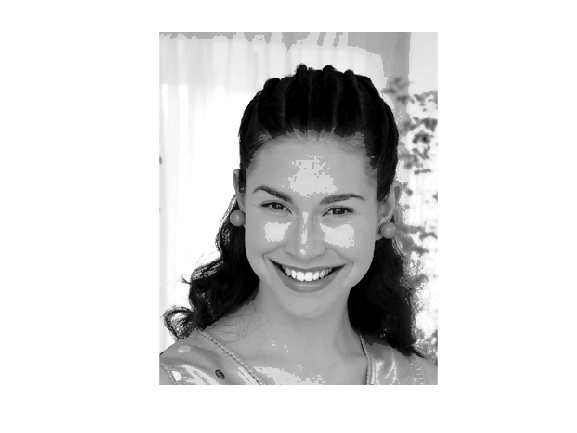

figure;
imshow(L5);

k15=find(L5==0)

k15 =        16617
       16996
       16997
       17375
       17376
       17377
       17755
       17756
       18160
       18162


k25=find(L5==255)

k25 =         1578
        1579
        1580
        1581
        1582
        1583
        1584
        1585
        1586
        1587


L6 = L5

L6 = 380×300 uint8 matrix
   171   174   175   175   175   175   175   177   179   177   175   174   176   174   172   169   168   168   169   173   176   178   178   178   175   175   176   176   176   175   172   170   164   161   165   168   171   173   173   171   168   171   171   171   171   171   172   173   173   173
   173   177   178   178   178   178   178   178   178   178   178   178   179   178   175   171   171   171   172   175   178   180   211   211   178   179   177   175   176   175   171   170   165   164   168   171   173   175   175   173   171   171   171   171   171   171   172   173   173   173
   177   180   211   211   211   180   180   179   178   178   180   211   211   180   178   175   173   174   174   177   211   212   213   213   180   211   179   176   176   175   172   170   167   168   171   173   175   178   178   175   173   172   171   171   171   171   172   173   173   173
   180   211   211   211   180   179   179   179   211   211   211   21

L6(find(L6>0 & L6<255)) = 128

L6 = 380×300 uint8 matrix
   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   128   128   128   128   128   128   128   128   128   128   128   12

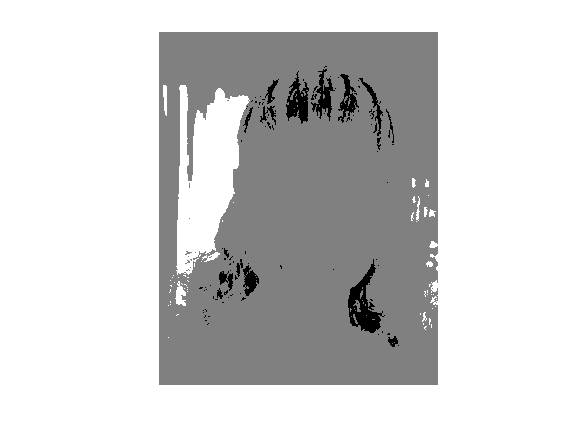

figure (Name='na szarym skrajne')
set(gcf,'Visible','on') %wymuszenie wydzielenia okna
imshow(L6);